disp("Question 1")

Question 1


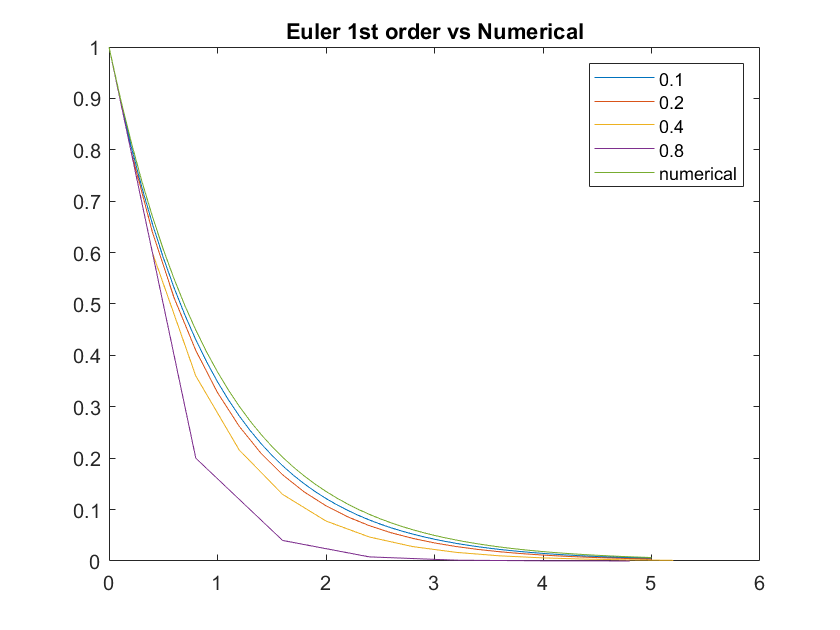


dt = [0.1, 0.2, 0.4, 0.8];
for i = 1:length(dt)
    [T, Y] = euler1stOrder(1, @deriv, dt(i), 5);
    plot(T, Y);%plot graph for each time difference
    hold on
end
t = 0:0.1:5;
plot(t, exp(-t));%plot numerical solution
title('Euler 1st order vs Numerical')
legend('0.1', '0.2', '0.4', '0.8', 'numerical');

disp(" ")

disp("Question 2")

Question 2


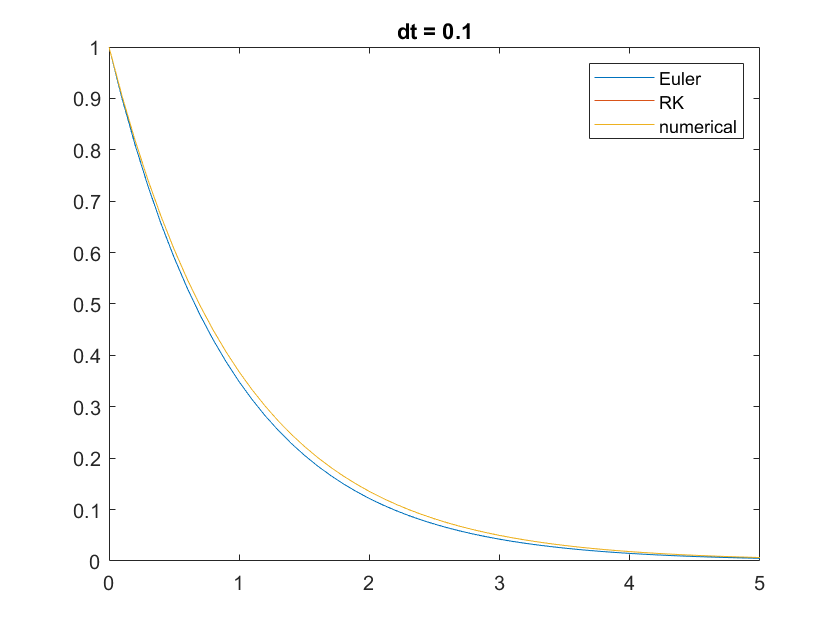

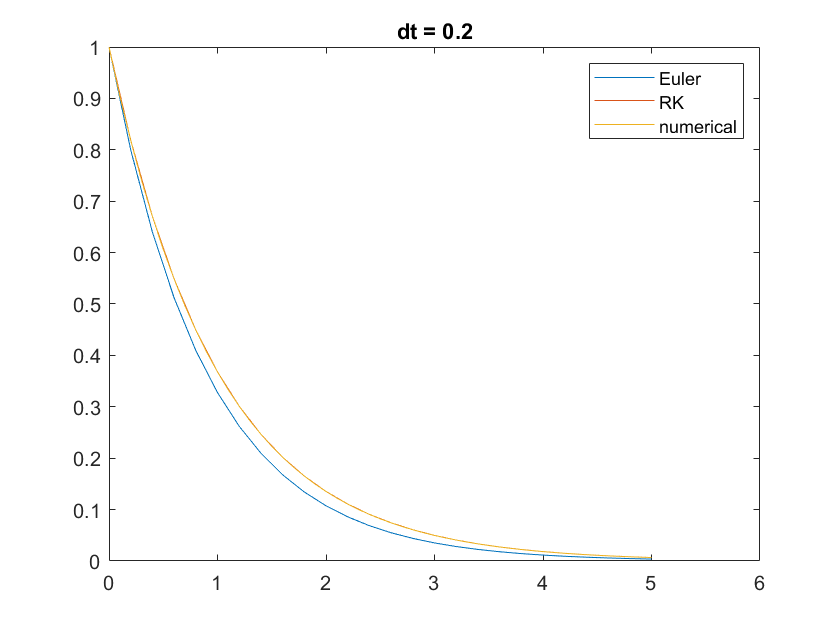

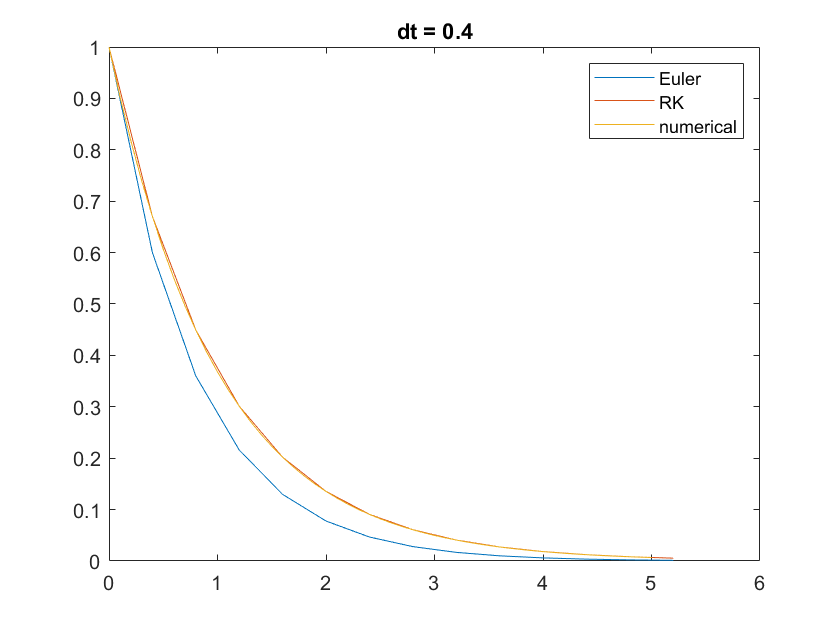

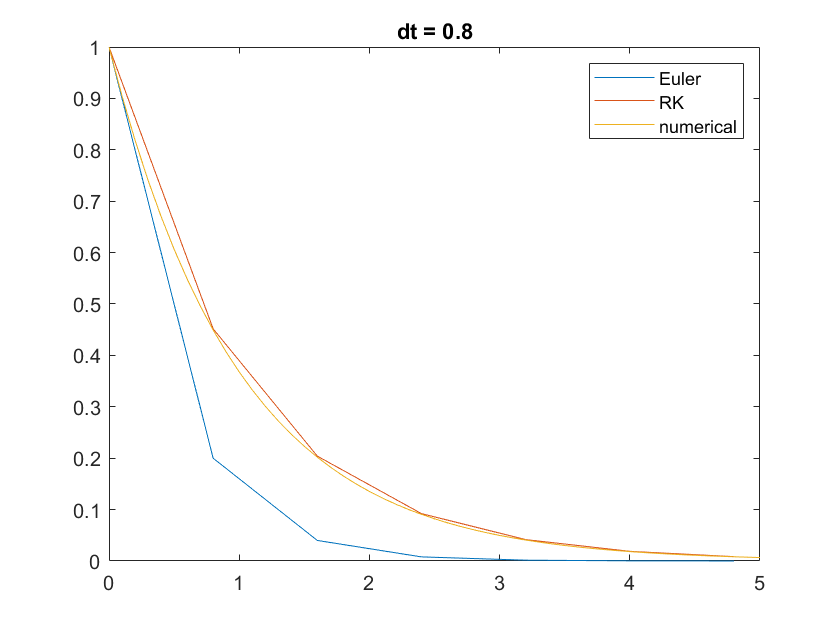


for i = 1:length(dt)
    figure()
    [T, Y] = euler1stOrder(1, @deriv, dt(i), 5);
    plot(T, Y);%plot Euler graph for each time difference
    hold on
    [T, Y] = runge_kutta_4(1, @deriv, dt(i), 5);
    plot(T, Y);%plot runge kutta graph for each time difference
    t = 0:0.1:5;
    plot(t, exp(-t))%plot numerical graph for each time difference
    title('dt = '+string(dt(i)))
    legend('Euler', 'RK', 'numerical')
end

disp(" ")

disp("Question 3")

Question 3


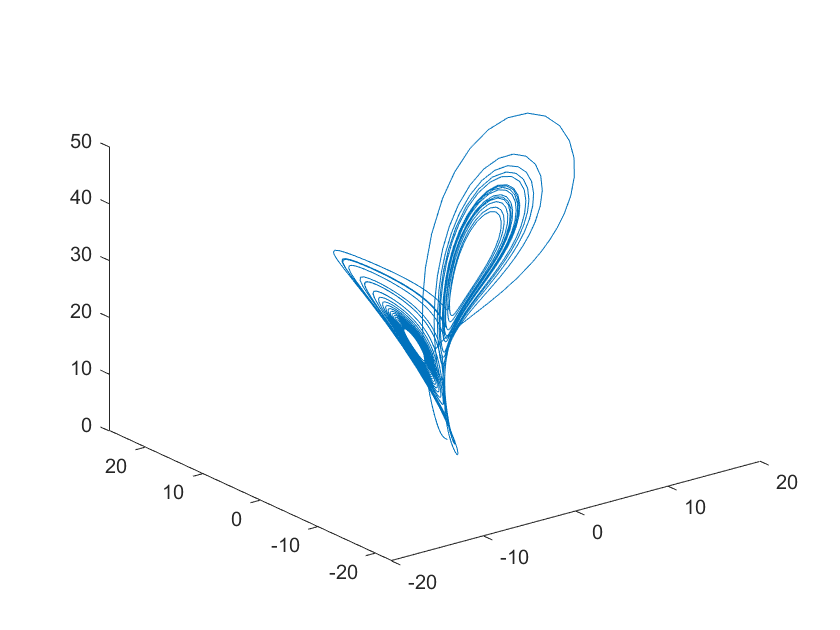


options = odeset('AbsTol',1e-6);%set tolerance to 1e-6
TSPAN = [0 30];
Y0 = [1, 1, 1];%initial values

[T, Y] = ode45(@equation, TSPAN, Y0, options);
figure()
x = Y(:,1);
y = Y(:,2);
z = Y(:,3);
plot3(x, y, z)

disp(" ")

disp("Question 4")

Question 4



syms x y;
Q4_1 = simplify(sin(x)^2+cos(x)^2)

$$Q4\_1 = 1$$

Q4_2 = simplify(sin(x)*cos(y)+sin(y)*cos(x))

$$Q4\_2 = \sin\left(x+y\right)$$

Q4_3 = simplify(cosh(x)^2-sinh(x)^2)

$$Q4\_3 = 1$$

disp(" ")

disp("Question 5")

Question 5



syms a b c A m
Q5_1 = solve(a^2==b^2+c^2-2*b*c*cos(A), b)

$$Q5\_1 = \left(\begin{array}{c} c\,\cos\left(A\right)+\sqrt{a^{2}+c^{2}\,{\cos\left(A\right)}^{2}-c^{2}}\\ c\,\cos\left(A\right)-\sqrt{a^{2}+c^{2}\,{\cos\left(A\right)}^{2}-c^{2}} \end{array}\right)$$

Q5_2 = solve(subs(a^2==b^2+c^2-2*b*c*cos(A), [a c A], [5*m 2*m 60*pi/180]), b)

$$Q5\_2 = \left(\begin{array}{c} m+\sqrt{22}\,m\\ m-\sqrt{22}\,m \end{array}\right)$$

disp(" ")

disp("Question 6")

Question 6


syms k1 k2 s p1 p2

A = [0 -1;5 2];
b = [0; 1];
K = [k1; k2];
Q6_1 = det(s*eye(2)-A+b*transpose(K))%finding the charactiristic equation

$$Q6\_1 = k_{2}\,s-2\,s-k_{1}+s^{2}+5$$

Q6_2 = (s+p1)*(s+p2)%pole placement equation

$$Q6\_2 = \left(p_{1}+s\right)\,\left(p_{2}+s\right)$$

coeff1 = coeffs(Q6_1, s);%coefficiant matrices
coeff2 = coeffs(Q6_2, s);

Q3_a = coeff1(1)==coeff2(1)%coefficiant of s^0

$$Q3\_a = 5-k_{1}=p_{1}\,p_{2}$$

Q3_b = coeff1(2)==coeff2(2)%coefficiant of s

$$Q3\_b = k_{2}-2=p_{1}+p_{2}$$

disp("4")

4


K1 = solve(subs(Q3_a,[p1 p2], [5 10]), k1)%solve for k1

$$K1 = -45$$

K2 = solve(subs(Q3_b, [p1 p2], [5 10]), k2)%solve for k2

$$K2 = 17$$

Functions

function dy = deriv(time, y)
dy = -y;
end

%2 b
function [t, y] = euler1stOrder(y0, f, dt, t_final)
time = 0;
Nsteps = round(t_final/dt);
t= zeros(Nsteps,1);
t(1) = 0;%intitial time value
y = zeros(Nsteps, 1);
y(1)= y0;%initial y value
for i = 1:Nsteps
    dy = f(time, y0);%f is the above deriv function
    y0 = y0 + dt*dy;%y0 = y0_previous + dt*dy
    time = time + dt;%dt is added to current time
    t(i+1) = time;%update time and y outputs
    y(i+1) = y0;
end
end

function [t, y] = runge_kutta_4(y0, f, dt, t_final)
Nsteps = round(t_final/dt);
t = zeros(length(Nsteps), 1);
t(1) = 0;
y = zeros(length(Nsteps), 1);
y(1) = y0;
for i = 1:Nsteps
    k1 = dt*f(t(i), y(i)); 
    k2 = dt*f(t(i)+dt/2, y(i)+k1/2);
    k3 = dt*f(t(i)+dt/2, y(i)+k2/2);
    k4 = dt*f(t(i)+dt, y(i)+k3);
    y(i+1) = y(i) + k1/6 + k2/3 + k3/3 + k4/6;%literaaly the definition of runge kutta straight from the notes
    t(i+1) = t(i) +dt;
end
end

function dy_dt = equation(t, y)
dy_dt = [10*(y(2)-y(1)); %dx/dt = 10(y-x)
        y(1)*(27-y(3))-y(2); %dy/dt = x(27-z)-y
        y(1)*y(2)-8*y(3)/3;]; %dz/dt = xy-8z/3
end